clc
clear

# **Kmeans**

### a) Generate a 2D uncorrelated Gaussian distributed training dataset

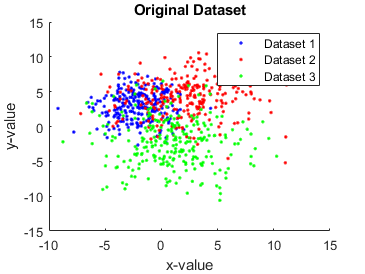

samples = 250;

%cluster 1 
mean1 = [-2; 3];
sd1 = 2;

%cluster 2
mean2 = [2; 4];
sd2 = 3;

%cluster 3
mean3 = [1; -2];
sd3 = 3.25;

dataset1 = sd1 * randn(2,samples) + repmat(mean1,1,samples);
dataset2 = sd2 * randn(2,samples) + repmat(mean2,1,samples);
dataset3 = sd3 * randn(2,samples) + repmat(mean3,1,samples);

%plot
hold on
plot(dataset1(1,:),dataset1(2,:),'b.')
plot(dataset2(1,:),dataset2(2,:),'r.')
plot(dataset3(1,:),dataset3(2,:),'g.')
xlabel('x-value')
ylabel('y-value')
title("Original Dataset")
legend('Dataset 1','Dataset 2','Dataset 3')
hold off

### b) Concatenate the datasets into a single dataset and plot all the points

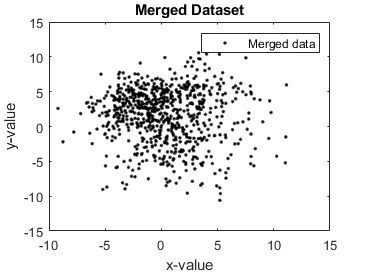

ConCluster = cat(2,dataset1,dataset2,dataset3);

plot(ConCluster(1,:),ConCluster(2,:),'black.')
title("Merged Dataset")
legend('Merged data')
xlabel('x-value')
ylabel('y-value')

### c) Given the number of clusters as 3, implement Kmeans clustering from first principles

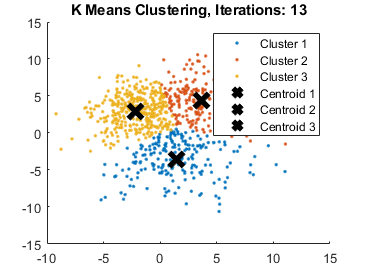

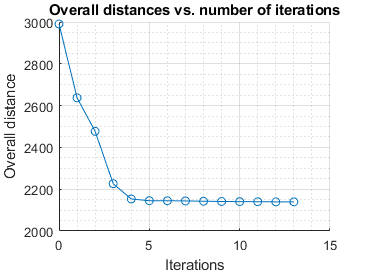

k = 3;
maxIterations = 1000;
a = kmeansClustering(ConCluster,k,maxIterations,true);

%calcVariation(a,k,true);

### d) If the number of clusters is unknown, explain and find out (via matlab code) the best number of clusters.

k = 10

k = 10

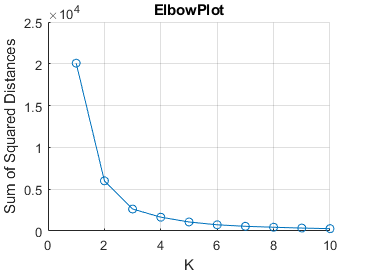

elbowPlot(ConCluster,k);

From observing the elbow plot I have determined the optimal value of k is 3, 

### e) From  your  observation  and  analysis,  what  are  the  limitations  or  drawbacks  of  Kmeans clustering?  

### Functions:

#### Elbow Plot function

function elbowPlot(ConCluster, max_K)
    allSSDist = [];
    for k = 1:max_K
        totalSSDist = 0;
        %Generate clusters
        clustInfo = kmeansClustering(ConCluster,k,1000,false);
        %Get some of squared distances
        sumSqu = calcSumSquDists(clustInfo,k,false);
        %check sumSqu has values
        if(size(sumSqu,2) ~= 0)
            for i = 1:k
                totalSSDist = totalSSDist + sumSqu(i);
            end
            allSSDist = [allSSDist,[totalSSDist;k]];
        end
    end
    figure    
    hold on
    xlabel('K')
    ylabel('Sum of Squared Distances')
    plot(allSSDist(2,:),allSSDist(1,:),"o-")
    title('ElbowPlot')
    grid on
    hold off
end

#### K means clustering function

function [results] = kmeansClustering(ConCluster,k,max_iterations,graphOn)
    %Initialise variables
    groupedClusters = [];

    %for j = 1:max_iterations
    done = false;
    iteration=0;

    centroidArray = [];
    clusterArray = [];
    totalDistance=0;
    totalDistances = [];

    %step 2 randomly select k destinct datapoints -> these are the initical clusters
    for cen = 1:k
        r = (randi([1,size(ConCluster,2)],1));
        centroid = [ConCluster(1,r);ConCluster(2,r)];
        centroidArray = [centroidArray, centroid];
    end
    %step 3 Measure the distances between each point and each initial centroid
    %assigning each to the centroids cluster
    for i  = 1:size(ConCluster,2)
        distArray = [];
        %loop through centroidArray
        for cen = 1:k
            %calculate distance from each point
            dist = sqrt((centroidArray(1,cen)-ConCluster(1,i))^2+(centroidArray(2,cen)-ConCluster(2,i))^2);
            %save distance in distance array
            distArray = [distArray,dist];
        end
        %step 4 Assign the point to the nearest cluster
        for d = 1:k
            %check if first distance
            if d == 1
                %save distance for next iteration
                bestDist = distArray(d);
                bestCentNum = d;
            else
                %get distance
                curDist = distArray(d);
                %compare with old distance
                if bestDist > curDist
                    %save distance for next iteration
                    bestDist = curDist;
                    bestCentNum = d;
                end
            end
        end
        totalDistance = totalDistance + bestDist;

        %assign point to nearest cluster
        %[ConCluster(1,i);ConCluster(2,i);bestCentNum];
        clusterArray = [clusterArray, [ConCluster(1,i);ConCluster(2,i);bestCentNum]];
    end

    totalDistances = [totalDistances,[iteration;totalDistance]];

    %step 5 repeat what just did (measure and cluster) using the mean
    %values as centroids
    while done==false
        bDistances = [];
        iteration = iteration +1;
        totalDistance = 0;
        newCentroidArray = [];
        %loop through centroids
        for cen = 1:k
            %get centroids cluster
            clustIdxs = find(clusterArray(3,:)==cen);
            clust = clusterArray(:,clustIdxs);
            %calc mean of that cluster and add to newClusterArray
            clustSize = size(clust,2);
            newCentroidArray = [newCentroidArray,[(sum(clust(1,:)))/clustSize;(sum(clust(2,:)))/clustSize]];
        end
        clusterArray = [];
        %Measure the distances between each point and each new centroid
        %assigning each to the centroids cluster
        for i  = 1:size(ConCluster,2)
            %reset distArray
            distArray = [];
            %loop through centroidArray
            for cen = 1:k
                %calculate distance from each point
                dist = sqrt((newCentroidArray(1,cen)-ConCluster(1,i))^2+(newCentroidArray(2,cen)-ConCluster(2,i))^2);
                %save distance in distance array
                distArray = [distArray,dist];
            end
            %Assign the point to the nearest cluster
            for d = 1:k
                %check if first distance
                if d == 1
                    %save distance for next iteration
                    bestDist = distArray(d);
                    bestCentNum = d;
                else
                    %get distance
                    curDist = distArray(d);
                    %compare with old distance
                    if bestDist > curDist
                        bestDist = curDist;
                        bestCentNum = d;
                    end
                end
            end
            totalDistance = totalDistance + bestDist;
            bDistances = [bDistances,bestDist];
            %assign point to nearest cluster
            clusterArray = [clusterArray, [ConCluster(1,i);ConCluster(2,i);bestCentNum]];

        end
        %add to total distances array
        totalDistances = [totalDistances,[iteration;totalDistance]];

        %if clustering does not change or max_iterations are reached then k-means is
        %complete
        if (centroidArray == newCentroidArray | iteration == max_iterations)
            %stop
            done=true;
            if graphOn
            figure
            hold on
            for cen = 1:k
                %get centroids cluster
                clustIdxs = find(clusterArray(3,:)==cen);
                clust = clusterArray(:,clustIdxs);
                %plot on graph
                pointName = append('Cluster ',int2str(cen));
                plot(clust(1,:),clust(2,:),'.','DisplayName',pointName)
                legend()
            end
            %Plot centroidArray
            for cen = 1:k
                pointName = append('Centroid ',int2str(cen));
                plot(newCentroidArray(1,cen),newCentroidArray(2,cen),'black x','MarkerSize',15,'linewidth',4,'DisplayName',pointName)
            end
            titleName = append('K Means Clustering, Iterations: ',int2str(iteration));
            title(titleName)
            hold off

            %plot distances and iterations
            figure
            hold on
            xlabel('Overall distances')
            ylabel('Iterations')
            plot(totalDistances(1,:),totalDistances(2,:),'o-')
            grid on
            grid minor
            xlabel('Iterations')
            ylabel('Overall distance')
            title('Overall distances vs. number of iterations')
            hold off
            end
            totalDistances = [];
            
            iteratoinMatrix = zeros(1,size(clusterArray,2));
            iteratoinMatrix(1,:) = iteration;
            clustWIt = cat(1,clusterArray, iteratoinMatrix);
            clustWIt = cat(1,clustWIt, bDistances);
            

            groupedClusters = [groupedClusters,clustWIt];

            %3d matrix
            %groupedClusters=cat(3,groupedClusters,clustWIt);

        else
            %continue
            done = false;

            centroidArray = newCentroidArray;
        end
    end
    
    %end
    results = groupedClusters;
end

#### Sum Squared Distance function

function [sumSquDist] = calcSumSquDists(data,kValue,graphOn)
    %initialise variables
    sumSquDist = [];
    totalSquDist = [];

    %check data contains values
    if (size(data,2) ~= 0)
        %loop through centroids
        for cen = 1:kValue
            b = 0;
            %get cluster == cen
            clustIdxs = find(data(3,:)==cen);
            clust = data(:,clustIdxs);
            for i = 1:size(clust,2)
                clust(5,i);
                b = b + (clust(5,i))^2;
            end
            squDist = b/kValue;
            totalSquDist = [totalSquDist; squDist];
        end
    end
    sumSquDist = [sumSquDist,totalSquDist];
    if graphOn
        figure
        bar(sumSquDist,'stacked')
    end
end